# Parametros geograficos y fronteras paises

%% Geographical bounds (expanded Mediterranean region)
long_min_bound = -10;
long_max_bound = 45;
lat_min_bound = 27;
lat_max_bound = 50;
% Read the shapefile for country boundaries
% Read the shapefile for country boundaries

countries = readgeotable("C:\Users\pache\Documents\AAB--Practicas\IMEDEA\CODIGO - DATOS" + ...
    "\\ne_10m_admin_0_countries\ne_10m_admin_0_countries.shp");



# Carga de datos


load("DATOS\twosat\Mediterraneo\Data_Anticiclonica_short_long_combinado.mat")
load("DATOS\twosat\Mediterraneo\Data_Cicllonica_short_long_combinado.mat")
load("CELDAS.mat")
% Show variables (fields) of the struct
fields = fieldnames(Data_ANC);

# Representación Por Celdas

trackAN = unique(Data_ANC.track); trackCIC = unique(Data_CIC.track);
nacimiento_celdasAN = zeros(1, length(cells));  % Inicializa el contador de celdas (ajusta según el número máximo de celdas)
vidamediaAN= zeros(1, length(cells));   % por celda

for j = 1:length(trackAN)
    % Acceder al valor de track en la posición j
    track_value = trackAN(j);
    
    % Encontrar los índices donde el 'track' es igual al valor actual
    idx = find(Data_ANC.track == track_value);
    
    % Filtrar las filas donde el valor de 'track' es igual al valor actual
    Celdas = Data_ANC.celda(idx);
    Lifetime= Data_ANC.lifetime(idx);% Extrae las celdas correspondientes
    num_celda = Celdas(1);  % primera celda para la trayectoria
    vida_max=max(Lifetime);

    if num_celda ~= 0
    % Incrementar el contador para esa celda
      nacimiento_celdasAN(num_celda) = nacimiento_celdasAN(num_celda) + 1;
      vidamediaAN(num_celda)=vidamediaAN(num_celda)+vida_max;
    end
end

for i = 1:length(nacimiento_celdasAN)
    % Asegurarse de que Cuenta_celdas(i) no sea cero
    if nacimiento_celdasAN(i) ~= 0
        vidamediaAN(i) = vidamedia(i) / nacimiento_celdasAN(i);  % Calcula la vida media
    else
        vidamediaAN(i) = 0;  % Si no hay celdas asociadas, la vida media será 0
    end
end

## Nacimientos

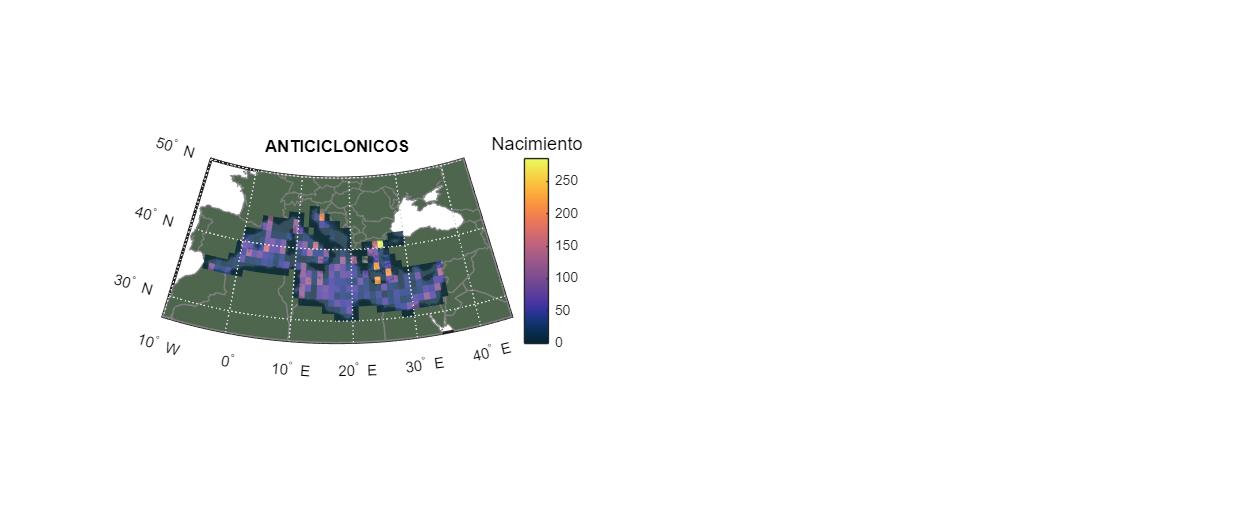



minC = min(nacimiento_celdasAN);  % Encuentra el valor mínimo
maxC = max(nacimiento_celdasAN);  % Encuentra el valor máximo
cmap =(cmocean('thermal'));  % Genera un mapa de colores con 80 colores

% Crea la figura
figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = nacimiento_celdasAN(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8
    
end
% Título y etiquetas
title(titulo);

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=(TituloColorbar);
cb.Title.FontSize = 12;

## Muertes 

## Vida Media 

## Ratio Ciclonicos/Anticiclonicos

# Representación sin CELDAS

#### Data

trackAN = unique(Data_ANC.track); trackCIC = unique(Data_CIC.track);

trayectoriasCIC={}; trayectoriasAN={};
% Inicializar un vector para almacenar las longitudes mínimas para cada track
NacimLon_AN = NaN(length(trackAN), 1); NacimLat_AN = NaN(length(trackAN), 1);
NacimLon_CIC = NaN(length(trackCIC ), 1); NacimLat_CIC = NaN(length(trackCIC ), 1);

MuertLon_AN = NaN(length(trackAN), 1); MuertLat_AN = NaN(length(trackAN), 1);
MuertLon_CIC = NaN(length(trackCIC ), 1); MuertLat_CIC = NaN(length(trackCIC), 1);

%REPRESENTA SOLO EVENTOS QUE DUREN MAS QUE, EN SEMANAS
LifetimeMinimo=2;

% Recorrer cada uno de los valores únicos de trackAN
for i = 1:length(trackAN)
    % Filtrar las filas de Data_ANC donde track es igual al valor actual de trackAN
    idxTrack = Data_ANC.track == trackAN(i);
    
    % Obtener las longitudes asociadas a ese track
    longitudesTrack = Data_ANC.longitude(idxTrack);
    latitudesTrack = Data_ANC.latitude(idxTrack);
   
    VidaANC=Data_ANC.lifetime(idxTrack);
    
    if max(VidaANC)/7 >= LifetimeMinimo
        trayectoriasAN{i} = [latitudesTrack, longitudesTrack]; 
        % Obtener el valor mínimo de longitud para ese track
        NacimLon_AN(i) = min(longitudesTrack);
        NacimLat_AN(i)= min(latitudesTrack);
    
        MuertLon_AN(i) = max(longitudesTrack);
        MuertLat_AN(i)= max(latitudesTrack);
    end
end

% Recorrer cada uno de los valores únicos de trackCIC
for i = 1:length(trackCIC)
    % Filtrar las filas de Data_ANC donde track es igual al valor actual de trackAN
    idxTrackC = Data_CIC.track == trackCIC(i);
    
    % Obtener las longitudes asociadas a ese track
    longitudesTrackC = Data_CIC.longitude(idxTrackC);
    latitudesTrackC = Data_CIC.latitude(idxTrackC);

    VidaCIC=Data_CIC.lifetime(idxTrackC);

    if max(VidaCIC)/7 >= LifetimeMinimo
        trayectoriasCIC{i} = [latitudesTrackC, longitudesTrackC]; 
        % Obtener el valor mínimo de longitud para ese track
        NacimLon_CIC(i) = min(longitudesTrackC);
        NacimLat_CIC(i)= min(latitudesTrackC);
    
        MuertLon_CIC(i) = max(longitudesTrackC);
        MuertLat_CIC(i)= max(latitudesTrackC);
    end
end



#### Representación Nacimientos

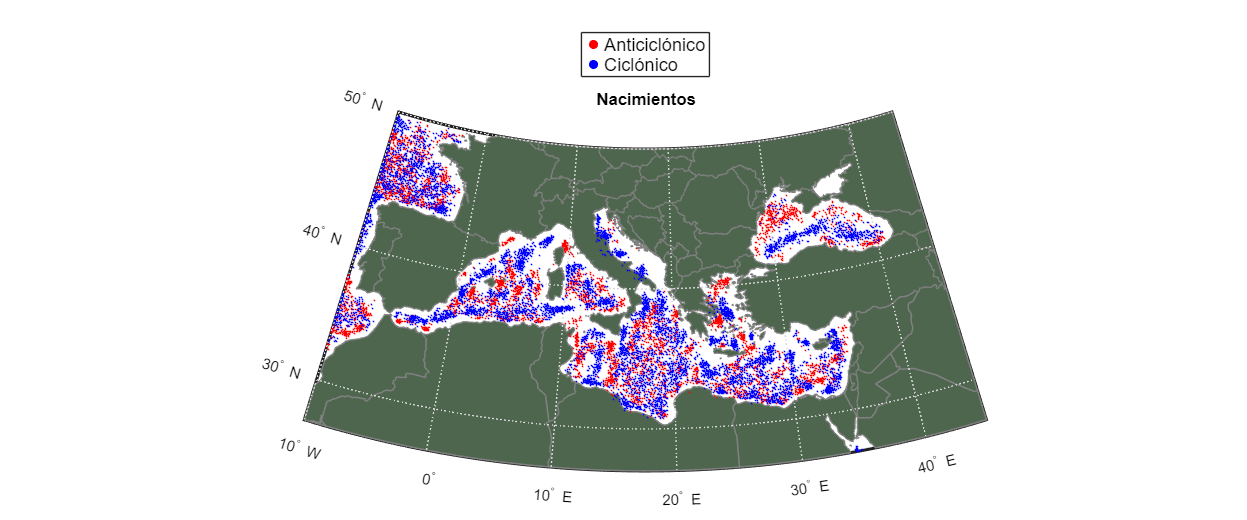

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

geoshow(NacimLat_AN, NacimLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","red");
geoshow(NacimLat_CIC, NacimLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","blue");




% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);

title("Nacimientos")
xlabel("Longitud")
ylabel("Latitud")

#### Representación Muertes

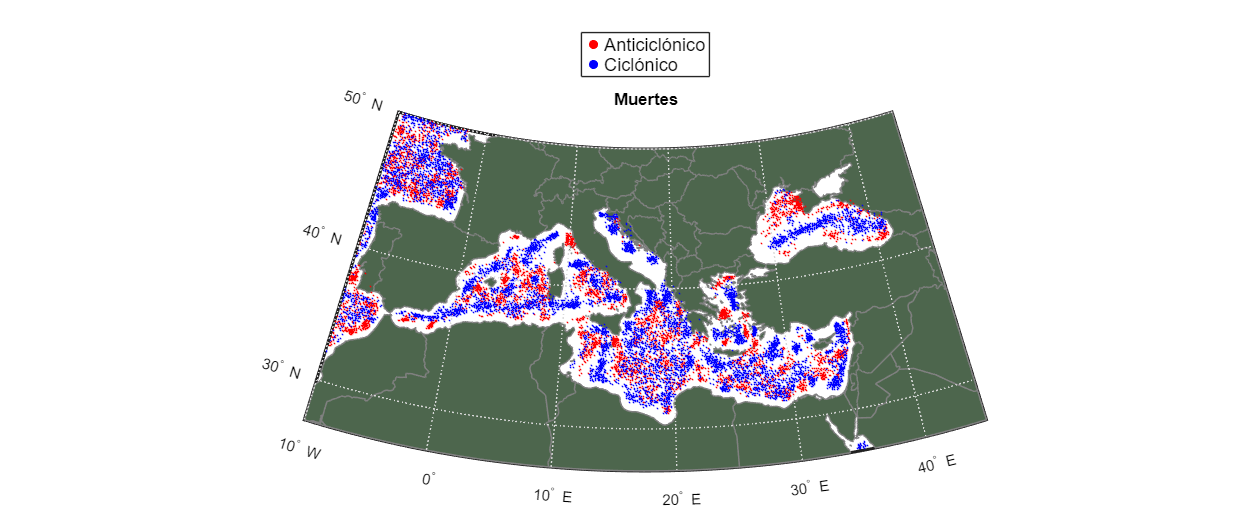

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

geoshow(MuertLat_AN, MuertLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","red");
geoshow(MuertLat_CIC, MuertLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","blue");

% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);

grid on
title("Muertes")
xlabel("Longitud")
ylabel("Latitud")

#### Representación Conjunta Muertes y Nacimientos

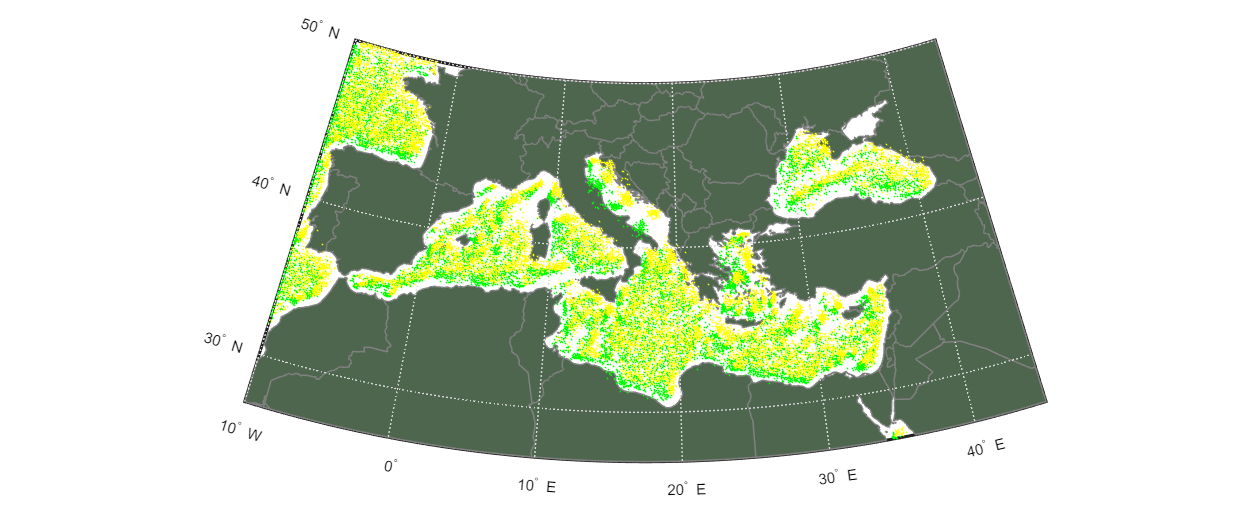

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

geoshow(NacimLat_AN, NacimLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","green");
geoshow(NacimLat_CIC, NacimLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","green");

geoshow(MuertLat_AN, MuertLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color",'yellow');
geoshow(MuertLat_CIC, MuertLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color",'yellow');

#### Trayectorias

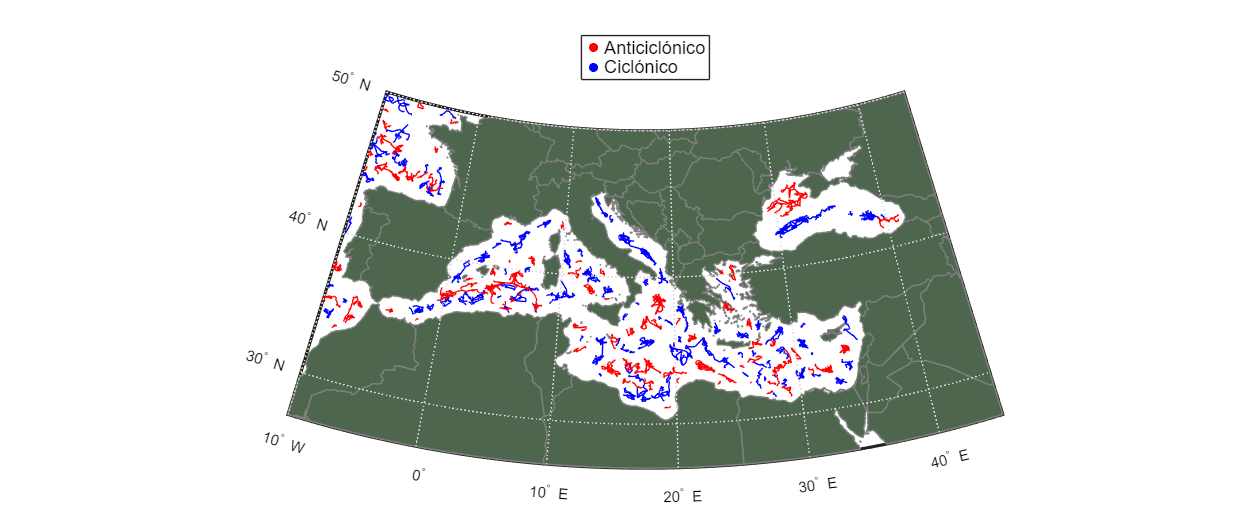


figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');
% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);


% Recorrer todas las trayectorias almacenadas en la celda
for i = 1:length(trayectoriasCIC)/50
    datos = trayectoriasCIC{i}; % Extraer la matriz de la celda
    if isempty(datos)
        continue; % Saltar esta iteración si la celda está vacía
    end
    latitudes = datos(:,1);
    longitudes = datos(:,2);% Segunda columna: longitudes
    
    % Dibujar la trayectoria con geoshow
    geoshow(latitudes, longitudes, 'DisplayType', 'line', 'Color', 'blue', 'LineWidth', 0.1);
end

for i = 1:length(trayectoriasAN)/50
    datos = trayectoriasAN{i}; % Extraer la matriz de la celda
    if isempty(datos)
        continue; % Saltar esta iteración si la celda está vacía
    end
    latitudes = datos(:,1);
    longitudes = datos(:,2);% Segunda columna: longitudes
    
    % Dibujar la trayectoria con geoshow
    geoshow(latitudes, longitudes, 'DisplayType', 'line', 'Color', 'red', 'LineWidth', 0.1);
end


% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);